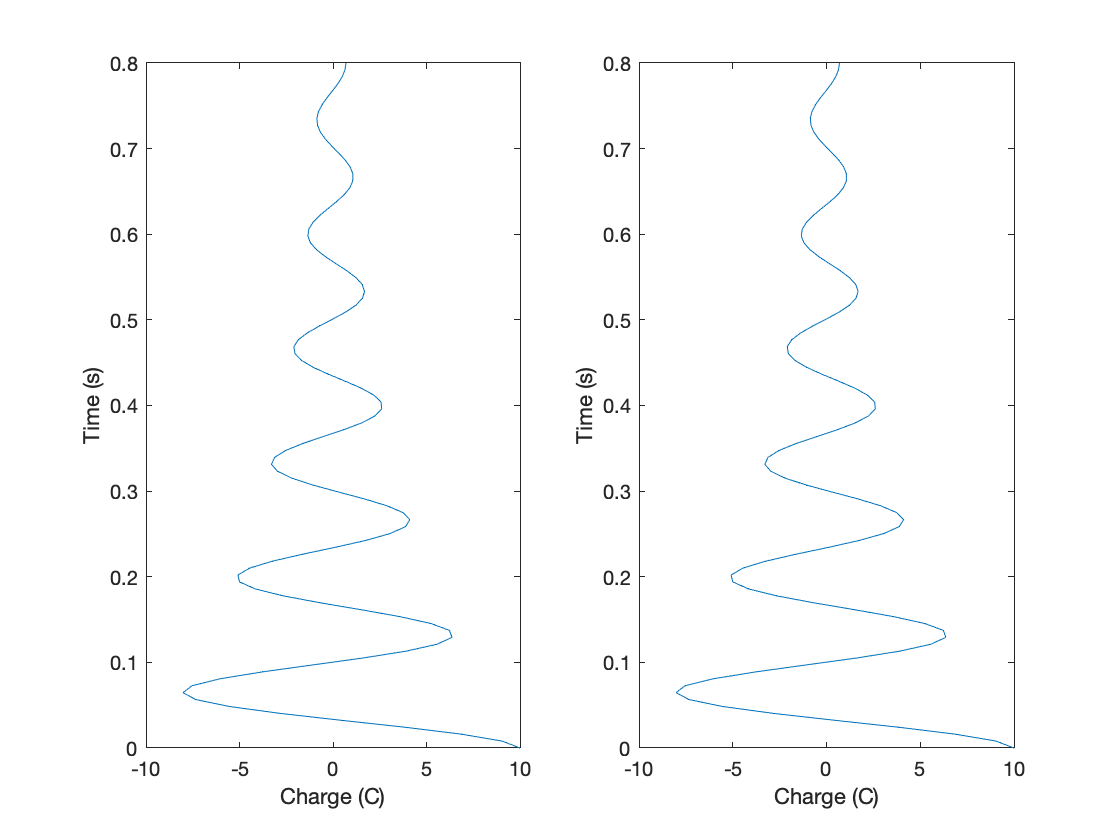

% Function parameters
q0 = 10;
R = 60;
L = 9;
C = 0.00005;
C2 = 0.0005;
e = 2.71828;

% Use linspace to create an array of 100 points between 0 and 0.8
t = linspace(0,0.8,100);

% Calculate the values of q
%Original: q = q0.*(e.^(-R.*t/2.*L)) .* cos(sqrt((1/(L.*C))-(((R/2.*L).^2).*t)))

q_pt1 = (-R*t)/(2*L);
q_pt2 = q0*e.^(q_pt1);

q_pt3 = (1/(L*C)) - ((R/(2*L))^2);
q_pt4 = (sqrt(q_pt3))*t;
q_pt5 = cos(q_pt4);

q = q_pt2 .* q_pt5;

%q = q0.*(e.^(-R.*t/2.*L)) .* cos(sqrt((1/(L.*C))-(((R/2.*L).^2).*t)));

% Plot q vs t
%plot(q,t)
%xlabel('Charge (C)')
%ylabel('Time (s)')

% Make the capacitor 10x bigger
%Orginial: q2 = q0.*(e.^(-R.*t/2.*L)) .* cos(sqrt((1/L.*(C*10))-(((R/2.*L).^2).*t)));

%q2 = q0.*(e.^(-R.*t/2.*L)) .* cos(sqrt((1/L.*(C*10))-(((R/2.*L).^2).*t)));

q2_pt1 = (-R*t)/(2*L);
q2_pt2 = q0*e.^(q_pt1);

q2_pt3 = (1/(L*(C2))) - ((R/(2*L))^2);
q2_pt4 = (sqrt(q_pt3))*t;
q2_pt5 = cos(q_pt4);

q2 = q_pt2 .* q_pt5;

% Plot q2 vs t
subplot(1,2,1)
plot(q,t)
xlabel('Charge (C)')
ylabel('Time (s)')
subplot(1,2,2)
plot(q2,t)
xlabel('Charge (C)')
ylabel('Time (s)')


%subplot(q2,t)
